# Offline RL for GBWM — Week 5 Plan C: Drawdown Penalty Reward

Diagnosis from v1+v2: lambda-on-loss reward shaping is saturated. Mean Sharpe went 0.25 -> 0.37 -> 0.50 across v3/v1/v2, but MaxDD P90 went 12.87% -> 14.40% -> 15.41% (wrong direction) and worst Sharpe stayed around -5.7. Root cause: lambda multiplies losses uniformly across all actions on stress days, so DQN learns "stress regime has lower value" rather than "in stress, defensive > aggressive".

Plan C replaces lambda shaping with an explicit drawdown penalty that is inherently ACTION-DEPENDENT (aggressive allocations produce larger DD by construction). No stress gate needed — drawdown itself is the regime signal.

Literature anchor: - Risk-Sensitive DRL for Portfolio Optimization (MDPI JRFM 2025): MPLS framework uses drawdown penalty in reward and reports +40-70% Sharpe improvement with controlled drawdown during COVID stress. - Moody & Saffell 1998: incremental risk-adjusted reward principle.

Everything else (state dim, network, agent, eval windows, seeds) IDENTICAL to v3. The stress gate is gone — drawdown plays its role automatically.

clear; clc;

## Fixed Parameters (copied from v3)

initialWealth   = 100000;
goalWealth      = 102000;
contribution    = 0;
rebalanceStep   = calmonths(1);

trainingRange   = 2515;
horizonPeriods  = 30;
numEpisodes     = 165;
numActions      = 15;

logsRoot        = fullfile("experiments", "logs", "week5_drawdown_penalty");

hiddenUnits     = 32;
maxEpochs       = 100;
stepsPerEpoch   = 400;
miniBatchSize   = 256;
discountFactor  = 0.995;

seeds           = [1000 2000 3000 4000 5000];
nSeeds          = numel(seeds);

numEvalEpisodes = 30;
evalStepSize    = 30;

% NEW — drawdown penalty params (REPLACES VIX_THR/SLOPE_THR/LAMBDA from v1/v2)
BETA   = 5.0;     % drawdown penalty coefficient
DD_THR = 0.03;    % tolerance: no penalty until DD exceeds 3%

## Load price data

pricesTT   = readtable("data/prices_train.csv");
assetNames = pricesTT.Properties.VariableNames(2:end);
P_train    = pricesTT{:, 2:end};
R_train    = diff(log(P_train));

R_sub = R_train(1:trainingRange, :);
mu    = mean(R_sub, 1)';
Sigma = cov(R_sub);

p = Portfolio("AssetList", assetNames);
p = setDefaultConstraints(p);
p = setAssetMoments(p, mu, Sigma);
W_frontier = estimateFrontier(p, numActions);

## Load macro data, z-score on train (state-only, no longer used for reward gate)

macroTT   = readtable("data/macro_train.csv");
M_train   = macroTT{:, 2:end};
macroMean = mean(M_train, 1);
macroStd  = std(M_train, 0, 1);
macroStd(macroStd == 0) = 1;
M_train_z = (M_train - macroMean) ./ macroStd;

## Load + z-score test data

[R_full, M_test_z] = inputTestData('data/prices_test.csv', 'data/macro_test.csv', ...
                                    macroMean, macroStd);

## Cross-seed result storage

results = struct();
results.successRate     = nan(nSeeds, 1);
results.meanSharpe      = nan(nSeeds, 1);
results.stdSharpe       = nan(nSeeds, 1);
results.meanMaxDD       = nan(nSeeds, 1);
results.stdMaxDD        = nan(nSeeds, 1);
results.meanTermWealth  = nan(nSeeds, 1);
results.p10TermWealth   = nan(nSeeds, 1);
results.p90TermWealth   = nan(nSeeds, 1);
results.minSharpe       = nan(nSeeds, 1);
results.p90MaxDD        = nan(nSeeds, 1);
results.actionHist      = zeros(nSeeds, numActions);
results.penaltyShare    = nan(nSeeds, 1);   % share of training steps that incurred penalty
results.meanPenalty     = nan(nSeeds, 1);   % avg penalty magnitude when active

allWealthPathsBySeed = cell(nSeeds, 1);

normalizeWealth = @(w) min(w/goalWealth, 5);
timeFrac        = @(t) t / horizonPeriods;

obsDim = 2 + size(M_train_z, 2);

## Loop over seeds

for sIdx = 1:nSeeds
    seed = seeds(sIdx);
    rng(seed, "twister");

    fprintf("\n========== Seed %d (%d/%d) ==========\n", seed, sIdx, nSeeds);

    seedLogsFolder = fullfile(logsRoot, sprintf("seed_%d", seed));
    if isfolder(seedLogsFolder)
        delete(fullfile(seedLogsFolder, "*.mat"));
    else
        mkdir(seedLogsFolder);
    end

    % --- Build offline episodes with drawdown-penalty reward ---
    episodeCount      = 0;
    startIdx          = 1;
    stepSize          = floor(horizonPeriods/2);
    nPenaltySteps     = 0;
    penaltySum        = 0;

    while episodeCount < numEpisodes && (startIdx + horizonPeriods - 1) <= size(R_sub,1)
        episodeCount = episodeCount + 1;
        expStruct = repmat(struct("Observation",[],"Action",[],"Reward",[], ...
            "NextObservation",[],"IsDone",[]), horizonPeriods, 1);

        wealth = initialWealth;
        peakW  = initialWealth;     % NEW: per-episode running peak

        for t = 1:horizonPeriods
            dayIdx   = startIdx + t - 1;
            macroVec = M_train_z(dayIdx, :)';
            obs      = [normalizeWealth(wealth); timeFrac(t); macroVec];

            aIdx = randi(numActions);
            w    = W_frontier(:, aIdx);

            r_tp1      = R_sub(dayIdx, :) * w;
            wealthNext = (wealth + contribution) * (1 + r_tp1);

            % NEW reward formulation
            peakW   = max(peakW, wealthNext);
            DD_t    = (peakW - wealthNext) / peakW;
            penalty = BETA * max(0, DD_t - DD_THR);
            reward  = log(wealthNext / wealth) - penalty;

            if penalty > 0
                nPenaltySteps = nPenaltySteps + 1;
                penaltySum    = penaltySum + penalty;
            end

            if t == horizonPeriods && wealthNext >= goalWealth
                reward = reward + 1.0;
            end

            nextDayIdx   = min(dayIdx + 1, size(M_train_z, 1));
            nextMacroVec = M_train_z(nextDayIdx, :)';
            nextObs      = [normalizeWealth(wealthNext); ...
                            timeFrac(min(t+1, horizonPeriods)); ...
                            nextMacroVec];
            isDone       = (t == horizonPeriods);

            expStruct(t).Observation     = {obs};
            expStruct(t).Action          = {aIdx};
            expStruct(t).Reward          = reward;
            expStruct(t).NextObservation = {nextObs};
            expStruct(t).IsDone          = isDone;

            wealth = wealthNext;
        end

        epFile = fullfile(seedLogsFolder, sprintf("loggedData%03d.mat", episodeCount));
        exp = expStruct;
        save(epFile, "exp");
        startIdx = startIdx + stepSize;
    end

    totalSteps = episodeCount * horizonPeriods;
    results.penaltyShare(sIdx) = nPenaltySteps / totalSteps;
    if nPenaltySteps > 0
        results.meanPenalty(sIdx) = penaltySum / nPenaltySteps;
    else
        results.meanPenalty(sIdx) = 0;
    end
    fprintf("  Saved %d episodes (%d transitions). Penalty-active steps: %d (%.1f%%), avg magnitude %.4f\n", ...
        episodeCount, totalSteps, nPenaltySteps, 100*results.penaltyShare(sIdx), ...
        results.meanPenalty(sIdx));

    % --- File datastore ---
    myReadFcn = @(fname) load(fname, "exp").exp;
    fds = fileDatastore(fullfile(seedLogsFolder, "loggedData*.mat"), ...
                        "ReadFcn", myReadFcn);

    % --- Build fresh agent ---
    obsInfo = rlNumericSpec([obsDim 1], Name="GBWMObservation");
    actInfo = rlFiniteSetSpec(1:numActions, Name="AllocationIndex");

    criticLG = layerGraph([
        featureInputLayer(obsInfo.Dimension(1), Name="state")
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(numActions, Name="Qout")
        ]);

    criticNet = dlnetwork(criticLG);
    critic    = rlVectorQValueFunction(criticNet, obsInfo, actInfo);

    agentOpts = rlDQNAgentOptions( ...
        DiscountFactor=discountFactor, ...
        ExperienceBufferLength=1e6, ...
        MiniBatchSize=miniBatchSize, ...
        TargetUpdateMethod="periodic", ...
        TargetUpdateFrequency=4, ...
        UseDoubleDQN=true);
    agentOpts.CriticOptimizerOptions.LearnRate         = 5e-4;
    agentOpts.CriticOptimizerOptions.GradientThreshold = 1;
    agent = rlDQNAgent(critic, agentOpts);

    % --- Train ---
    tfdOpts = rlTrainingFromDataOptions( ...
        MaxEpochs        = maxEpochs, ...
        NumStepsPerEpoch = stepsPerEpoch, ...
        Plots            = "none", ...
        Verbose          = false);
    trainFromData(agent, fds, tfdOpts);
    save(fullfile(seedLogsFolder, "TrainedAgent.mat"), "agent");

    % --- Hold-out evaluation (raw wealth, no reward shaping) ---
    successCount   = 0;
    allSharpes     = nan(numEvalEpisodes, 1);
    allMaxDD       = nan(numEvalEpisodes, 1);
    allTermWealth  = nan(numEvalEpisodes, 1);
    allWealthPaths = cell(numEvalEpisodes, 1);
    allActions     = zeros(numEvalEpisodes, horizonPeriods);

    for ep = 1:numEvalEpisodes
        startEval = (ep-1)*evalStepSize + 1;
        if startEval + horizonPeriods - 1 > size(R_full, 1)
            break;
        end

        wealth = zeros(horizonPeriods+1, 1);
        wealth(1) = initialWealth;
        chosenActions = zeros(1, horizonPeriods);
        for t = 1:horizonPeriods
            dayIdx   = startEval + t - 1;
            macroVec = M_test_z(dayIdx, :)';
            obs      = { [normalizeWealth(wealth(t)); timeFrac(t); macroVec] };
            aGreedy  = agent.getAction(obs);
            chosenActions(t) = aGreedy{1};
            w        = W_frontier(:, aGreedy{1});
            r_tp1    = R_full(dayIdx, :) * w;
            wealth(t+1) = (wealth(t) + contribution) * (1 + r_tp1);
        end

        rets    = diff(log(wealth));
        sharpe  = mean(rets) / std(rets) * sqrt(252);
        maxDD   = max(cummax(wealth) - wealth) / max(wealth);

        allSharpes(ep)     = sharpe;
        allMaxDD(ep)       = maxDD;
        allTermWealth(ep)  = wealth(end);
        allWealthPaths{ep} = wealth;
        allActions(ep, :)  = chosenActions;
        successCount       = successCount + double(wealth(end) >= goalWealth);
    end

    results.successRate(sIdx)    = successCount;
    results.meanSharpe(sIdx)     = mean(allSharpes,'omitnan');
    results.stdSharpe(sIdx)      = std(allSharpes,'omitnan');
    results.meanMaxDD(sIdx)      = mean(allMaxDD,'omitnan');
    results.stdMaxDD(sIdx)       = std(allMaxDD,'omitnan');
    results.meanTermWealth(sIdx) = mean(allTermWealth,'omitnan');
    results.p10TermWealth(sIdx)  = prctile(allTermWealth, 10);
    results.p90TermWealth(sIdx)  = prctile(allTermWealth, 90);
    results.minSharpe(sIdx)      = min(allSharpes);
    results.p90MaxDD(sIdx)       = prctile(allMaxDD, 90);
    for a = 1:numActions
        results.actionHist(sIdx, a) = sum(allActions(:) == a);
    end

    allWealthPathsBySeed{sIdx} = allWealthPaths;

    fprintf("  Success %d/%d | Sharpe %.2f±%.2f | MaxDD %.2f%%±%.2f%% | TermW %.0f (P10 %.0f)\n", ...
        successCount, numEvalEpisodes, ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx));
end


========== Seed 1000 (1/5) ==========


  Saved 165 episodes (4950 transitions). Penalty-active steps: 893 (18.0%), avg magnitude 0.1168


  Success 13/30 | Sharpe 0.74±3.30 | MaxDD 6.92%±5.00% | TermW 101338 (P10 89946)



========== Seed 2000 (2/5) ==========


  Saved 165 episodes (4950 transitions). Penalty-active steps: 866 (17.5%), avg magnitude 0.1094


  Success 10/30 | Sharpe 0.07±3.11 | MaxDD 5.95%±4.99% | TermW 99186 (P10 89211)



========== Seed 3000 (3/5) ==========


  Saved 165 episodes (4950 transitions). Penalty-active steps: 906 (18.3%), avg magnitude 0.1298


  Success 10/30 | Sharpe 0.35±2.81 | MaxDD 6.23%±3.60% | TermW 100637 (P10 94910)



========== Seed 4000 (4/5) ==========


  Saved 165 episodes (4950 transitions). Penalty-active steps: 856 (17.3%), avg magnitude 0.1514


  Success 9/30 | Sharpe 0.21±3.10 | MaxDD 6.03%±5.97% | TermW 99466 (P10 93959)



========== Seed 5000 (5/5) ==========


  Saved 165 episodes (4950 transitions). Penalty-active steps: 950 (19.2%), avg magnitude 0.1380


  Success 11/30 | Sharpe 0.45±2.72 | MaxDD 4.10%±2.64% | TermW 100317 (P10 94500)


## Cross-seed summary

fprintf("\n\n===== Cross-seed summary (n=%d seeds) — Week 5 Plan C drawdown penalty =====\n", nSeeds);



===== Cross-seed summary (n=5 seeds) — Week 5 Plan C drawdown penalty =====


fprintf("Reward shaping       : BETA = %.2f   DD_THR = %.3f   (no stress gate)\n", BETA, DD_THR);

Reward shaping       : BETA = 5.00   DD_THR = 0.030   (no stress gate)


fprintf("Penalty-active share : %.1f%% of training steps (avg across seeds)\n", ...
    100*mean(results.penaltyShare));

Penalty-active share : 18.1% of training steps (avg across seeds)


fprintf("Success rate         : %.1f / %d  (std %.2f)\n", ...
    mean(results.successRate), numEvalEpisodes, std(results.successRate));

Success rate         : 10.6 / 30  (std 1.52)


fprintf("Mean Sharpe          : %.2f (across-seed std %.2f)\n", ...
    mean(results.meanSharpe), std(results.meanSharpe));

Mean Sharpe          : 0.36 (across-seed std 0.25)


fprintf("Within-seed Sharpe std : %.2f (avg)\n", mean(results.stdSharpe));

Within-seed Sharpe std : 3.01 (avg)


fprintf("Mean MaxDD           : %.2f%% (across-seed std %.2f%%)\n", ...
    mean(results.meanMaxDD)*100, std(results.meanMaxDD)*100);

Mean MaxDD           : 5.84% (across-seed std 1.05%)


fprintf("Mean Terminal Wealth : %.0f (across-seed std %.0f)\n", ...
    mean(results.meanTermWealth), std(results.meanTermWealth));

Mean Terminal Wealth : 100189 (across-seed std 875)


fprintf("Terminal P10 (avg)   : %.0f\n", mean(results.p10TermWealth));

Terminal P10 (avg)   : 92505


fprintf("Worst Sharpe (avg)   : %.2f   <-- v3: -5.78 | v1: -5.57 | v2: -5.80\n", ...
    mean(results.minSharpe));

Worst Sharpe (avg)   : -5.38   <-- v3: -5.78 | v1: -5.57 | v2: -5.80


fprintf("MaxDD P90 (avg)      : %.2f%% <-- v3: 12.87%% | v1: 14.40%% | v2: 15.41%%\n", ...
    mean(results.p90MaxDD)*100);

MaxDD P90 (avg)      : 11.79% <-- v3: 12.87% | v1: 14.40% | v2: 15.41%



fprintf("\n--- Per-seed table ---\n");


--- Per-seed table ---


fprintf("seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10)\n");

seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10)


for sIdx = 1:nSeeds
    fprintf("%4d | %4d | %5.2f ± %4.2f    | %5.2f%% ± %4.2f%%  | %.0f / %.0f\n", ...
        seeds(sIdx), results.successRate(sIdx), ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx));
end

1000 |   13 |  0.74 ± 3.30    |  6.92% ± 5.00%  | 101338 / 89946
2000 |   10 |  0.07 ± 3.11    |  5.95% ± 4.99%  | 99186 / 89211
3000 |   10 |  0.35 ± 2.81    |  6.23% ± 3.60%  | 100637 / 94910
4000 |    9 |  0.21 ± 3.10    |  6.03% ± 5.97%  | 99466 / 93959
5000 |   11 |  0.45 ± 2.72    |  4.10% ± 2.64%  | 100317 / 94500



fprintf("\n--- Action histogram (all eval steps) ---\n");


--- Action histogram (all eval steps) ---


totalHist = sum(results.actionHist, 1);
totalSteps = sum(totalHist);
for a = 1:numActions
    if totalHist(a) > 0
        fprintf("  action %2d : %4d (%.1f%%)\n", a, totalHist(a), 100*totalHist(a)/totalSteps);
    end
end

  action  1 :   69 (1.5%)
  action  2 :  226 (5.0%)
  action  3 :  698 (15.5%)
  action  4 :  118 (2.6%)
  action  5 :    7 (0.2%)
  action  6 :  249 (5.5%)
  action  7 :    6 (0.1%)
  action  8 :   24 (0.5%)
  action  9 : 1605 (35.7%)
  action 10 :   14 (0.3%)
  action 11 :  770 (17.1%)
  action 12 :   24 (0.5%)
  action 13 :  121 (2.7%)
  action 14 :  380 (8.4%)
  action 15 :  189 (4.2%)


## Plot — aggregated wealth band across all seeds

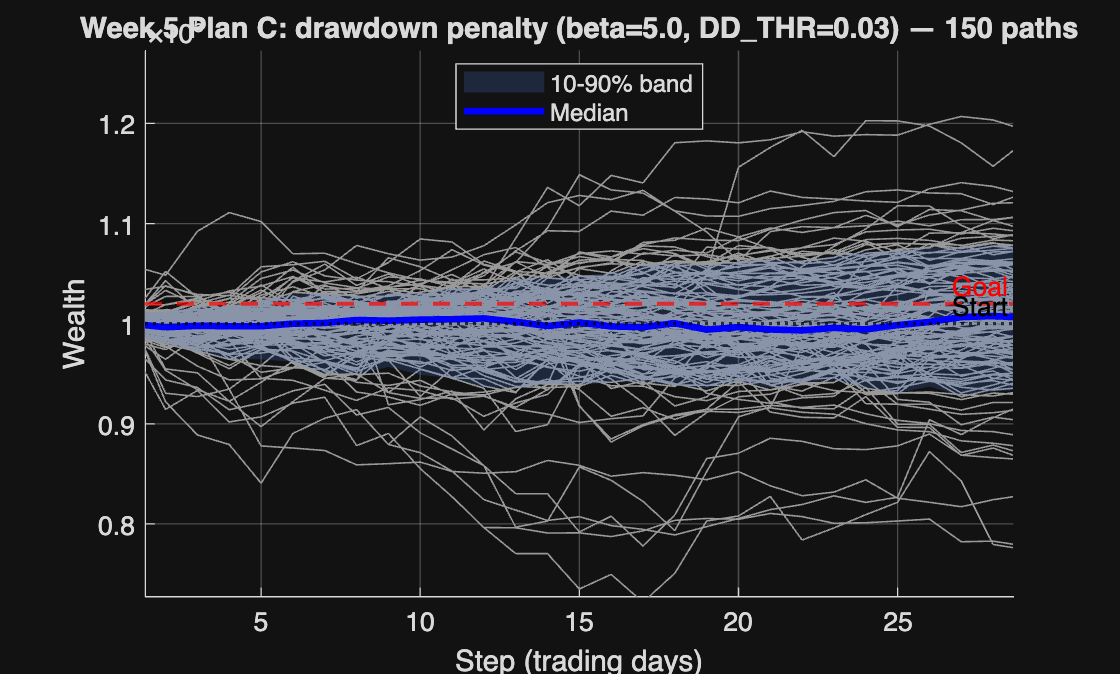

figure('Name','Hold-out wealth paths (Week 5 Plan C drawdown penalty)');
hold on;

allPathsFlat = nan(nSeeds * numEvalEpisodes, horizonPeriods + 1);
rowCursor = 0;
for sIdx = 1:nSeeds
    paths = allWealthPathsBySeed{sIdx};
    for ep = 1:numel(paths)
        if ~isempty(paths{ep})
            rowCursor = rowCursor + 1;
            allPathsFlat(rowCursor, :) = paths{ep}';
        end
    end
end
allPathsFlat = allPathsFlat(1:rowCursor, :);

steps = 0:horizonPeriods;

for r = 1:size(allPathsFlat, 1)
    plot(steps, allPathsFlat(r, :), 'Color', [0.6 0.6 0.6 0.15], ...
        'LineWidth', 0.6, 'HandleVisibility', 'off');
end

p10 = prctile(allPathsFlat, 10, 1);
p90 = prctile(allPathsFlat, 90, 1);
fill([steps, fliplr(steps)], [p10, fliplr(p90)], [0.3 0.5 0.9], ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '10-90% band');
plot(steps, median(allPathsFlat, 1, 'omitnan'), 'b-', 'LineWidth', 2.5, ...
    'DisplayName', 'Median');

yline(goalWealth, '--r', 'Goal', 'LineWidth', 1.5, 'HandleVisibility', 'off');
yline(initialWealth, ':k', 'Start', 'LineWidth', 1.2, 'HandleVisibility', 'off');

xlabel('Step (trading days)');
ylabel('Wealth');
title(sprintf('Week 5 Plan C: drawdown penalty (beta=%.1f, DD\\_THR=%.2f) — %d paths', ...
    BETA, DD_THR, rowCursor));
legend('Location','best');
grid on;

## Local Functions

function [R, M_z] = inputTestData(priceFile, macroFile, macroMean, macroStd)
    pricesTT = readtable(priceFile, 'VariableNamingRule', 'preserve');
    P = pricesTT{:, 2:end};
    R = diff(log(P));

    macroTT = readtable(macroFile, 'VariableNamingRule', 'preserve');
    M = macroTT{:, 2:end};
    M_z = (M - macroMean) ./ macroStd;
end